# HW7

Yuyu Fan

Problem1

clear; close all;
load hw7_1_data1
Yn=Yn';
[N, I] = size(Yn);
K = 5;
C(:,:,1) = Yn(1:K,:); % the first five dots


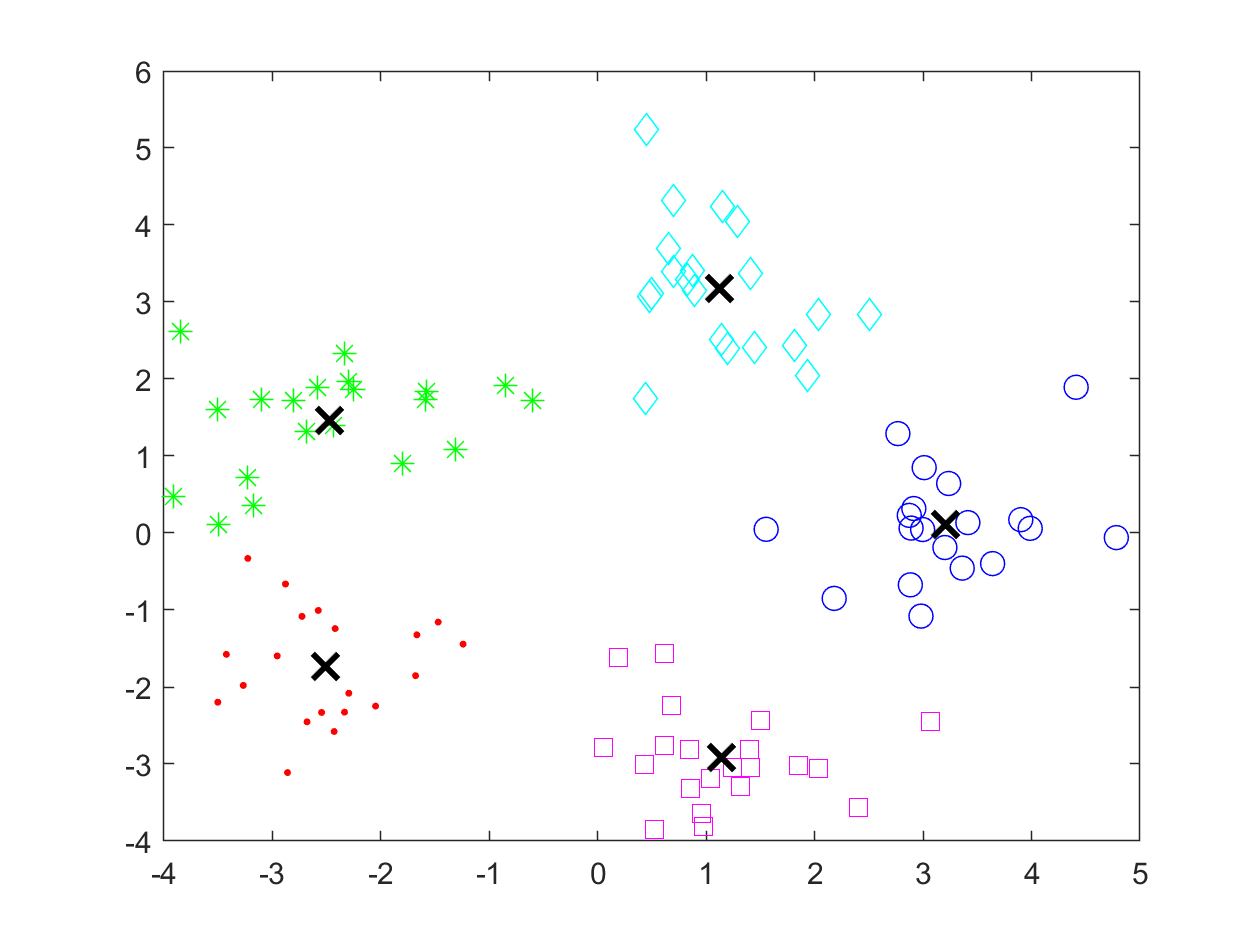

E = 1;
m = 1;
while (E > 1e-3)
 % assignment step %
 for n = 1:N
   dis = sqrt(sum((ones(K,1)*Yn(n,:) - C(:,:,m)).^2,2));
   [min_dis(m,n), ind(m,n)] = min(dis);
 end
 % update step %
 for k = 1:K
   C(k,:,m+1) = mean(Yn(ind(m,:)==k,:));
 end
 E = norm(C(:,:,m+1)-C(:,:,m));
 
 figure(1); clf;
 color = 'rbgcmyk';
 style = '.o*ds';
 for k = 1:K
  % plot all the observations %
  plot(Yn(ind(m,:)==k,1),Yn(ind(m,:)==k,2),[color(k) style(k)],'MarkerSize',8);
  hold on;
  % plot five means %
  plot(C(k,1,m),C(k,2,m),'kx', 'MarkerSize',12,'LineWidth',2)
 end
  ss(m) = sum(min_dis(m,:).^2);
  m = m+1;
end

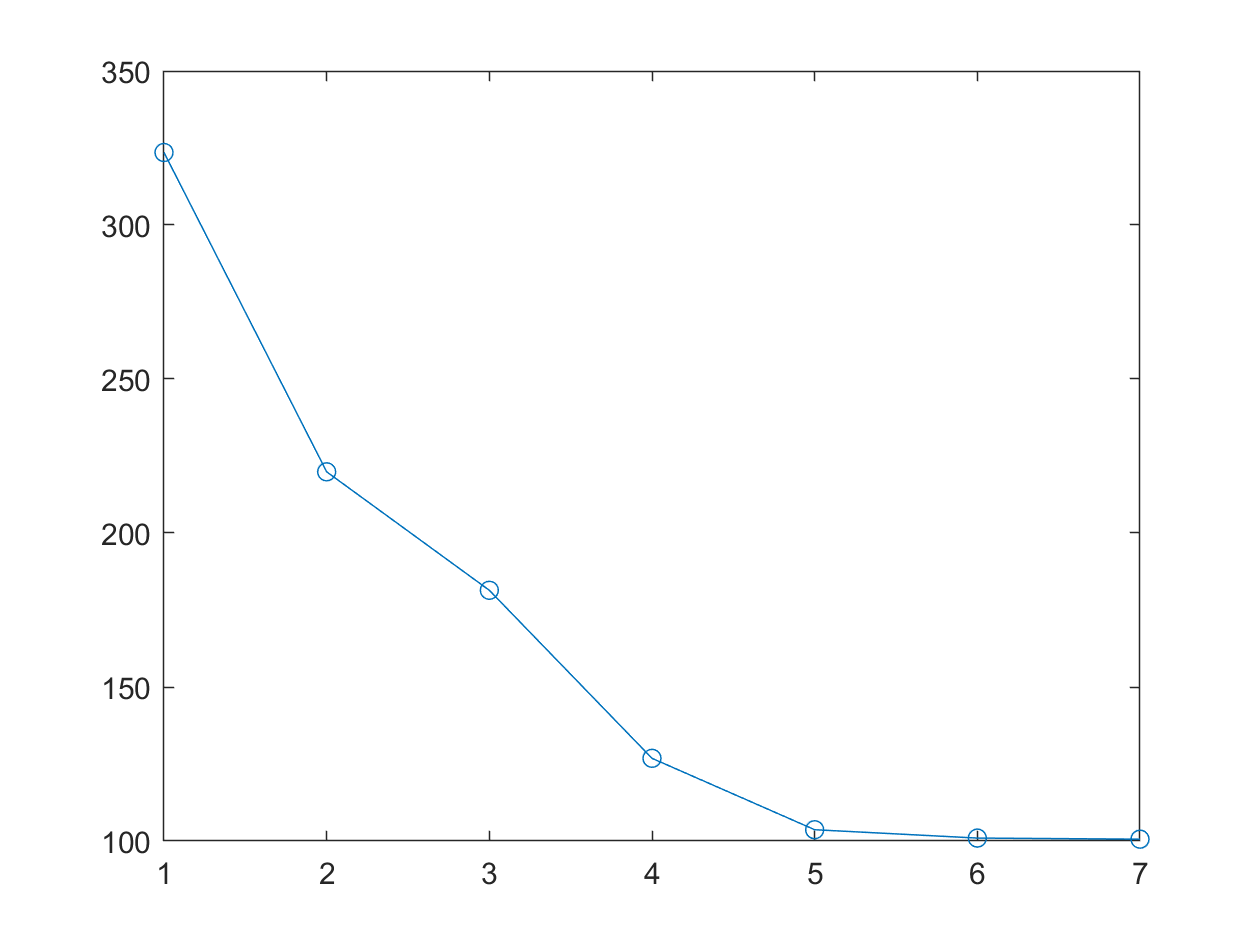


% (ii) plot the evolution of the sum of squared error versus the iteration index
figure(2);
plot(ss, 'o-');

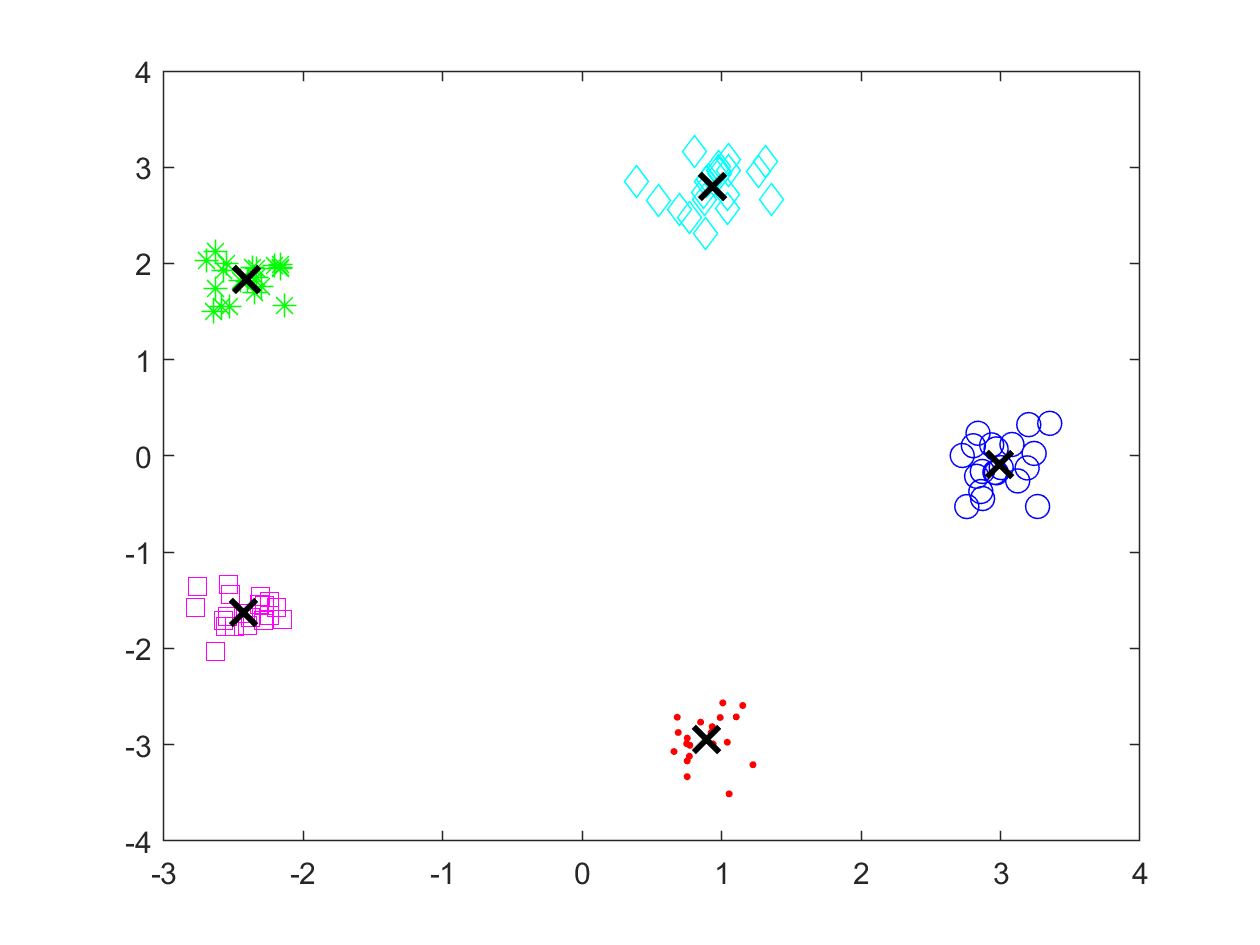

clear;
close all;
load hw7_1_data2
Yn=Yn';
[N, I] = size(Yn);
K = 5;
C(:,:,1) = Yn(20:19+K,:); % this choice leads to better result
E = 1;
m = 1;

while (E > 1e-3)
 for n = 1:N
   dis = sqrt(sum((ones(K,1)*Yn(n,:) - C(:,:,m)).^2,2));
   [min_dis(m,n), ind(m,n)] = min(dis);
 end
 for k = 1:K
   C(k,:,m+1) = mean(Yn(ind(m,:)==k,:));
 end
  E = norm(C(:,:,m+1)-C(:,:,m));
  
figure(1);
clf;
color = 'rbgcmyk';
style = '.o*ds';
 for k = 1:K
   plot(Yn(ind(m,:)==k,1),Yn(ind(m,:)==k,2),[color(k) style(k)],'MarkerSize',8);
   hold on;
   plot(C(k,1,m),C(k,2,m),'kx', 'MarkerSize',12,'LineWidth',2)
 end
  ss(m) = sum(min_dis(m,:).^2);
  m = m+1;
end

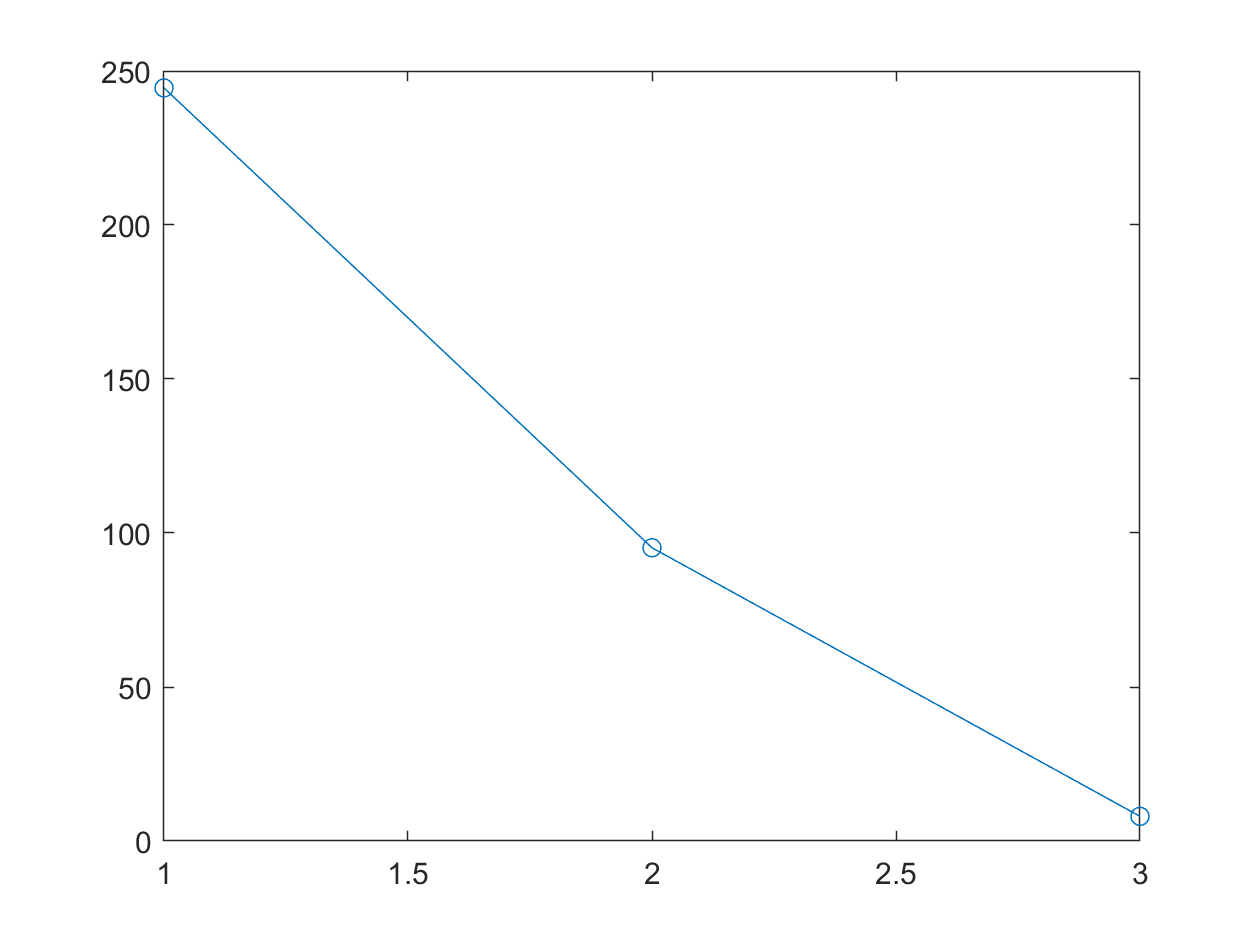


figure(2);
plot(ss, 'o-');

Problem 2

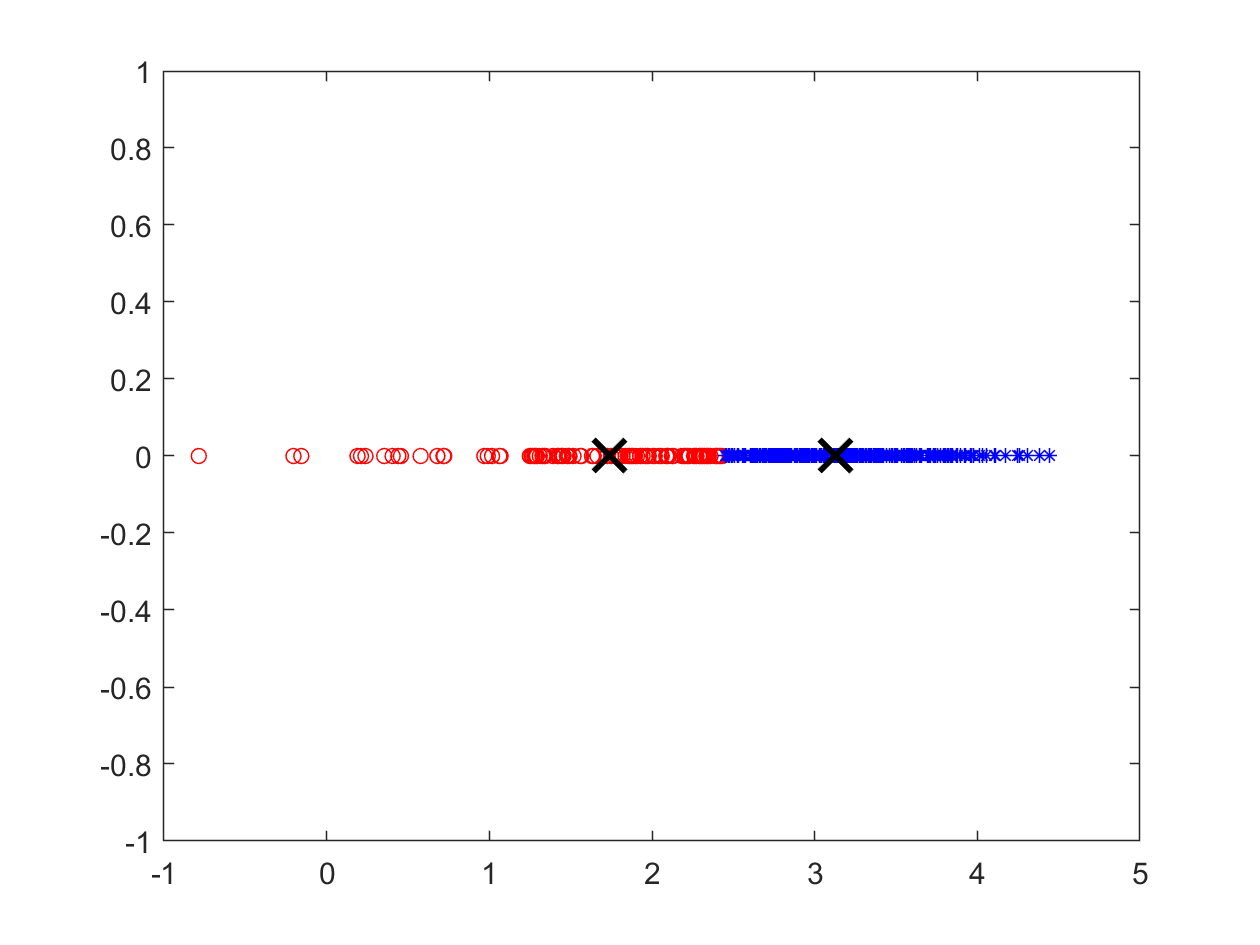

clear;
close all;
load hw6_2_data2
N = length(Y);
Y=[Y' zeros(N,1)];
K = 2;
C(:,:,1) = Y(1:K,:);
E = 1;
m = 1;

while (E > 1e-3)
 for n = 1:N
  dis = sqrt(sum((ones(K,1)*Y(n,:) - C(:,:,m)).^2,2));
  [min_dis(m,n), ind(m,n)] = min(dis);
 end
 for k = 1:K
  C(k,:,m+1) = mean(Y(ind(m,:)==k,:));
 end
 E = norm(C(:,:,m+1)-C(:,:,m));
 
 figure(1);
 clf;
 color = 'rbgcmyk';
 style = 'o*ds';
 for k = 1:K
    plot(Y(ind(m,:)==k,1),Y(ind(m,:)==k,2),[color(k) style(k)],'MarkerSize',5);
    hold on;
    plot(C(k,1,m),C(k,2,m),'kx', 'MarkerSize',15,'LineWidth',2)
 end
  ss(m) = sum(min_dis(m,:).^2);
  m = m+1;
 end

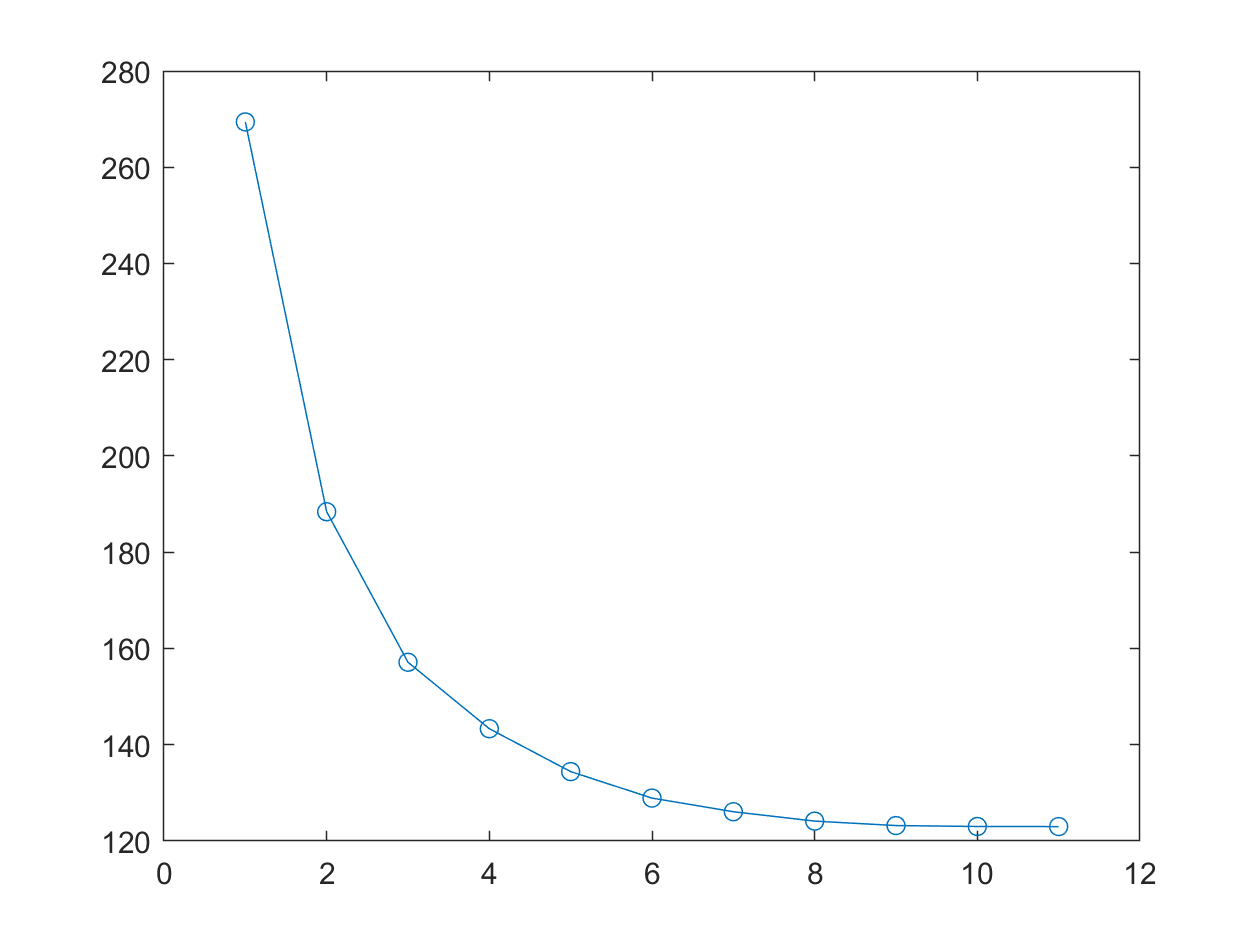


figure(2);
plot(ss, 'o-');

Y1 = Y(ind(m-1,:)==1,1);
Y2 = Y(ind(m-1,:)==2,1);

Mean_of_the_first_class = mean(Y1)

Mean_of_the_first_class = 1.7358

Variance_of_the_first_class = var(Y1)

Variance_of_the_first_class = 0.4410

Proportion_of_the_first_class = length(Y1)/N

Proportion_of_the_first_class = 0.2680

Mean_of_the_second_class = mean(Y2)

Mean_of_the_second_class = 3.1296

Variance_of_the_second_class = var(Y2)

Variance_of_the_second_class = 0.1763

Proportion_of_the_second_class = length(Y2)/N

Proportion_of_the_second_class = 0.7320

clear;
close all;
load hw6_2_data2
N = length(Y);
Y=[Y' zeros(N,1)];
K = 2;
C(:,:,1) = Y(1:K,:);
E = 1;
m = 1;

while (E > 1e-3)
 for n = 1:N
  dis = sqrt(sum((ones(K,1)*Y(n,:) - C(:,:,m)).^2,2));
  [min_dis(m,n), ind(m,n)] = min(dis);
 end
 for k = 1:K
  C(k,:,m+1) = mean(Y(ind(m,:)==k,:));
 end
 E = norm(C(:,:,m+1)-C(:,:,m));
 
 figure(1);
 clf;
 color = 'rbgcmyk';
 style = 'o*ds';
 for k = 1:K
    plot(Y(ind(m,:)==k,1),Y(ind(m,:)==k,2),[color(k) style(k)],'MarkerSize',5);
    hold on;
    plot(C(k,1,m),C(k,2,m),'kx', 'MarkerSize',15,'LineWidth',2)
 end
  ss(m) = sum(min_dis(m,:).^2);
  m = m+1;
 end


figure(2);
plot(ss, 'o-');

Y1 = Y(ind(m-1,:)==1,1);
Y2 = Y(ind(m-1,:)==2,1);

Mean_of_the_first_class = mean(Y1)

Mean_of_the_first_class = 1.7358

Variance_of_the_first_class = var(Y1)

Variance_of_the_first_class = 0.4410

Proportion_of_the_first_class = length(Y1)/N

Proportion_of_the_first_class = 0.2680

Mean_of_the_second_class = mean(Y2)

Mean_of_the_second_class = 3.1296

Variance_of_the_second_class = var(Y2)

Variance_of_the_second_class = 0.1763

Proportion_of_the_second_class = length(Y2)/N

Proportion_of_the_second_class = 0.7320